# Worldwide COVID-19 Patients Analysis using MATLAB

Data I collected from below link

[https://github.com/datasets/covid-19](https://github.com/datasets/covid-19)

## Read data as a table and name it as worldData

worldData=readtable('worldwide-aggregated.xlsx')

worldData = 79×4 table
       Date        Confirmed    Recovered    Deaths
    ___________    _________    _________    ______

    22-Jan-2020        555          28         17  
    23-Jan-2020        654          30         18  
    24-Jan-2020        941          36         26  
    25-Jan-2020       1434          39         42  
    26-Jan-2020       2118          52         56  
    27-Jan-2020       2927          61         82  
    28-Jan-2020       5578         107        131  
    29-Jan-2020       6166         126        133  
    30-Jan-2020       8234         143        171  
    31-Jan-2020       9927         222        213  
    01-Feb-2020      12038         284        259  
    02-Feb-2020      16787         472        362  
    03-Feb-2020      19881         623        426  
    04-Feb-2020      23892         852        492  
    05-F

Above data is preview of table, total data is from 23-02-2020 to 09-04-2020

## Plot current status of world 

**Extract active cases**

active_cases=worldData.Confirmed-worldData.Deaths-worldData.Recovered; 

**Plot confirmed cases, recovered cases,death cases and active cases**

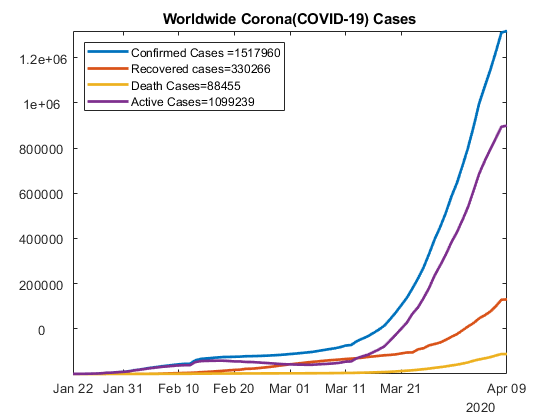

plot(worldData.Date,[worldData.Confirmed,worldData.Recovered,worldData.Deaths,active_cases],'LineWidth',2)
y_labels = get(gca, 'YTick'); % getting ydata
set(gca, 'YTickLabel', y_labels); % detting ydata as a label in current axis

legend(['Confirmed Cases ','=',num2str(worldData.Confirmed(end))],...
['Recovered cases','=',num2str(worldData.Recovered(end))],...
    ['Death Cases','=',num2str(worldData.Deaths(end))],...
    ['Active Cases','=',num2str(active_cases(end))], 'Location','northwest') % legend
axis tight
xticks([worldData.Date(1) worldData.Date(10:10:(end-10))' worldData.Date(end)]) % setting xticks manually
title('Worldwide Corona(COVID-19) Cases') % title of plot

## **Key Countries Analysis**

plot(worldData.Date,[worldData.Confirmed,worldData.Recovered,worldData.Deaths,active_cases],'LineWidth',2)
y_labels = get(gca, 'YTick'); % getting ydata
set(gca, 'YTickLabel', y_labels); % detting ydata as a label in current axis

legend(['Confirmed Cases ','=',num2str(worldData.Confirmed(end))],...
['Recovered cases','=',num2str(worldData.Recovered(end))],...
    ['Death Cases','=',num2str(worldData.Deaths(end))],...
    ['Active Cases','=',num2str(active_cases(end))], 'Location','northwest') % legend
axis tight
xticks([worldData.Date(1) worldData.Date(10:10:(end-10))' worldData.Date(end)]) % setting xticks manually
title('Worldwide Corona(COVID-19) Cases') % title of plotkeyCountires=readtable("key-countries-pivoted.xlsx");

xlim([datetime(2020,1,22,0,0,0)...
      datetime(2020,4,9,0,0,0)])
ylim([17 1517960])

**Plot current confirmed cases of key countries**

keyCountires=readtable('key-countries-pivoted.xlsx')

keyCountires = 78×9 table
       Date        China    US    United_Kingdom    Italy    France    Germany    Spain    Iran
    ___________    _____    __    ______________    _____    ______    _______    _____    ____

    22-Jan-2020      548     1          0             0        0          0         0       0  
    23-Jan-2020      643     1          0             0        0          0         0       0  
    24-Jan-2020      920     2          0             0        2          0         0       0  
    25-Jan-2020     1406     2          0             0        3          0         0       0  
    26-Jan-2020     2075     5          0             0        3          0         0      

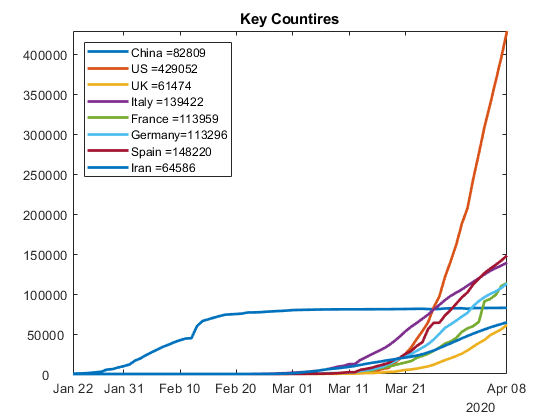

plot(keyCountires.Date,[keyCountires.China,keyCountires.US,...
    keyCountires.United_Kingdom,keyCountires.Italy,...
    keyCountires.France,keyCountires.Germany,...
    keyCountires.Spain,keyCountires.Iran],...
    'LineWidth',2)
y_labels = get(gca, 'YTick');
set(gca, 'YTickLabel', y_labels)
xticks([keyCountires.Date(1) keyCountires.Date(10:10:(end-10))' keyCountires.Date(end)])
axis tight

legend(['China ','=',num2str(keyCountires.China(end))],...
    [ 'US ','=',num2str(keyCountires.US(end))],...
    [ 'UK ','=',num2str(keyCountires.United_Kingdom(end))],...
    [ 'Italy ','=',num2str(keyCountires.Italy(end))],...
    [ 'France ','=',num2str(keyCountires.France(end))],...
    [ 'Germany','=',num2str(keyCountires.Germany(end))],...
    [ 'Spain ','=',num2str(keyCountires.Spain(end))],...
    [ 'Iran ','=',num2str(keyCountires.Iran(end))], 'Location','northwest')
title('Key Countires')

#### Bar plot of key countires

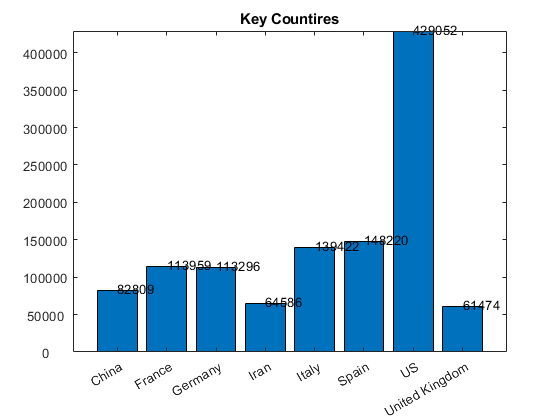

Key_Countries=categorical({'China','US','United Kingdom','Italy',...
    'France','Germany','Spain','Iran'});
bar(Key_Countries,[keyCountires.China(end),keyCountires.US(end),...
keyCountires.United_Kingdom(end),...
    keyCountires.Italy(end),...
    keyCountires.France(end),keyCountires.Germany(end),...
keyCountires.Spain(end),keyCountires.Iran(end)])
text(Key_Countries,[keyCountires.China(end),...
keyCountires.US(end),keyCountires.United_Kingdom(end),...
    keyCountires.Italy(end),...
    keyCountires.France(end),keyCountires.Germany(end)...
,keyCountires.Spain(end),keyCountires.Iran(end)]+3000,...
   string( ceil([keyCountires.China(end),keyCountires.US(end),keyCountires.United_Kingdom(end),...
    keyCountires.Italy(end),...
    keyCountires.France(end),keyCountires.Germany(end),...
keyCountires.Spain(end),keyCountires.Iran(end)])))
y_labels = get(gca, 'YTick');
set(gca, 'YTickLabel', y_labels)
axis tight
title('Key Countires')

#### Forecasting Worldwide for next one month using Nonlinear Least Squre Method 

you can use other regression methods there are various methods

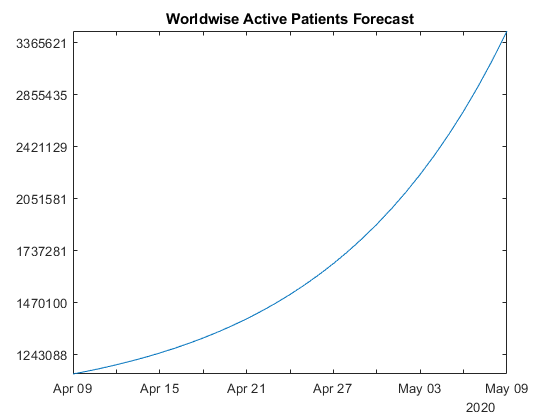

t=[1:length(worldData.Date)]';

[xData, yData] = prepareCurveData( t, active_cases );

% Set up fittype and options.
ft = fittype( 'exp2' );
opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
opts.Display = 'Off';
opts.StartPoint = [-111133.257565926 0.0441743219546307 96590.5673106364 0.0490456238054553];

% Fit model to data.
[fitresult, gof] = fit( xData, yData, ft, opts );

pred=fitresult(t(end):t(end)+30);
datee=worldData.Date(end):worldData.Date(end)+day(30);
plot(datee',ceil(pred))


axis tight
yticklabels(num2str([ceil(pred(1:2:end));ceil(pred(end))]))
title('Worldwise Active Patients Forecast')

As per above figure you can see till 9th May 2020 total COVID-19 patients are showing 14440000, but all countries are taking proper action to fight against corona so lets hope this graph will fall down.

For COVID-19 Forecast using Machine Learning

Watch my youtube video

[https://youtu.be/CGt2EYjmws0](https://youtu.be/CGt2EYjmws0)